## **BEATING THE STOCK MARKET USING SEASONAL INVESTING**

#### **Final Report for SYS 6014 at University of Virginia (Spring 2020)**

#### **Ryan Krechel - March 28, 2020**

**INTRODUCTION**

The goal for this project is to create a seasonal investing model to beat a buy-and-hold investment strategy using Vanguard ETFs. In theory, there are certain market trends that repeat at the same time each year. For instance, the beginning of December tends to be a time when investors sell off stocks to cover the cost of taxes, which generally causes losses in the stock market. If an investor is aware of this trend, he or she should choose to invest in less aggressive accounts (perhaps bonds) at this time of the year to protect assets and not lose any money. Seasonal investing is designed to take advantage of trends such as this and improve performance versus the traditional buy-and-hold approach. 

**BUILDING THE STRATEGY**

This project is built around a modified day-trading approach. Traditionally, day-trading is defined as picking an investment to purchase and sell in the same day. However, the method used in this report could be considered a week-trading approach. The decision maker in this analysis chooses an investment and sticks with it for a full week before selling. At the end of the week, the investor uses a new set of data to make a decision about where to invest for the next week. 

At each decision node (the beginning of a new week), the investor has the opportunity to choose a new fund using historical data for the week in question. This process is repeated for all 52 weeks of the calendar year to create a strategy, which is defined in this paper as investment instructions for the calendar year. Since all individual decisions are made using historical data from previous years, the investor can create a new strategy every time a full data set is collected; at the end of a calendar year. 

**DATA SELECTION AND CHOOSING FUNDS**

For the analysis, seven Vanguard exchange-traded funds (ETF) were chosen to cover differing sectors of the market and differing investment strategies (shown in Table 1). They each have different inception dates, with the newest being created in the middle of 2007. Therefore, to create a level playing field, data was only collected from 2008 to 2019.

TABLE 1: SUMMARY OF ETFs USED IN THIS ANALYSIS

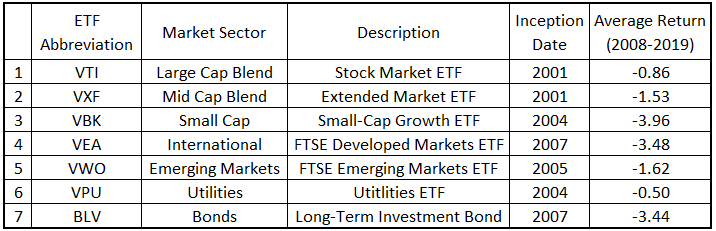

Clearly, the average for each fund is quite poor. This is largely due to a brutal 2008 recession that drives the averages down, but this presents the perfect opportunity to prove if this optimization method works since investing in any particular fund does not guarantee a good return based on averages.

**DEFINING SUCCESS**

In general, the goal is to beat a traditional buy-and-hold investment approach, which is defined as choosing to invest in any one of the ETFs used in this analysis for an extended period of time. The following table presents the yearly individual performance of each fund from 2008 to 2019.

TABLE 2: YEARLY INDIVIDUAL RETURNS SUMMARY

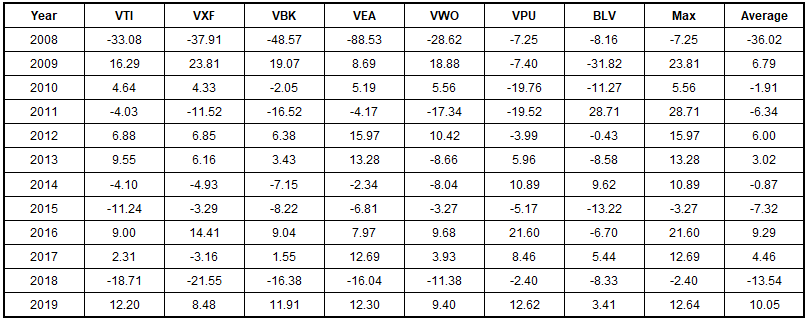

Since new data is collected very slowly (it takes an entire calendar year to add a full data set addition), success will be determined by taking a snapshot in time at some point in the past. For instance, data from 2008 to 2018 can be used to create a strategy that the decision maker could have chosen on December 31, 2018 to use during 2019. Since that data has already been collected, it can be used to test if the strategy chosen at that time would have worked. The goal is to prove that this method works before actually investing any real money.

It is difficult to define success for a single year, because returns are subject to so many random influences from world events not linked to a particular day or month. Because of this, the performance of a singular strategy is essentially arbitrary. However, when multiple years are strung together, the seasonal investing trends should become more evident and the method discussed in this paper can be more accurately evaluated.

Success of the method will be evaluated by comparing a string of yearly returns together and solving for a final value. Table 3 shows the combined individual yearly returns of 2013-2019 together as a total net percentage for each ETF, which represents the results of the long-term buy-and-hold approach. For instance, if an investor purchased $1000 worth of shares of VTI on December 31, 2012 and looked at their account on December 31, 2019, he or she would have $948, for a total return of -5.15%.

TABLE 3: AGGREGATE RETURNS FROM 2013-2019

The analysis done in this report starts with historical data from 2008 to 2012 to create a strategy for 2013. The actual return of the strategy will be calculated by using the strategy and recorded. At this point, a new strategy will be created by adding the new data set from 2012 and evaluating 2008-2013. This process will be repeated through 2019 and the total combined return of investment will be calculated. If the seasonal investment method is successful, the combined return will be greater than the data shown in Table 3.

**ACTION SET**

The decision-maker's action set *A* is a complete itemization of all the options available to the decision-maker, from which the decision-maker selects a unique choice. There are 8 actions available at the beginning of each week, which creates an incredible amount of different possible strategies. In fact, there are 8^52 different strategies! The options available at each decision node in this model are shown in Table 4.

TABLE 4: ACTION SET

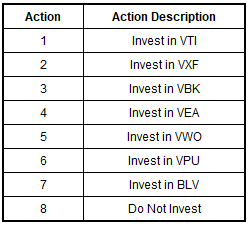

**DATA GENERATING PROCESS**

Data will be collected using Yahoo's share price history tool from 2008-2019. Preprocessing will be done on the "open" and "close" prices to convert the share prices into daily percentage losses or gains. This will be produced and uploaded into Matlab code with the corresponding dates to use in the analysis.

Once the raw data is uploaded into Matlab, it will be sorted by date and by gain/loss. The code will be written to assess January 1st as a specific decision node with available historical data from January 1st through January 7th, the first week of the year. Within this week's worth of data, there will be both positive gains and negative losses. These gains and losses will be sorted and separated to solve for the chance of both positive and negative return (evaluated by counting the days of positive and negative return and solving for a percentage), as well as real average positive and negative return (evaluated by averaging the historical returns).

In this way, the historical success of each ETF can be solved for any given week, both in likelihood of positive return and average value of positive/negative return. This will be done for the performance of each individual ETF on a week-to-week basis and is important because trends in weekly performance should become evident. If for some random reason, VTI has historically produced better returns for the first week of January, it will be identified as the optimal investment opportunity. Perhaps this is truly random, or perhaps it is a seasonal trend that the method can identify and exploit. This is the reason for doing this analysis! The hope is that a random superiority of VTI during a particular week has less to do with random data and more to do with a particular trend that repeats year to year.

The code will repeat this process for each calendar week (decision node) to develop a "strategy" for the year.

**PRIOR BELIEFS**

Average yearly returns are presented in Table 1, which give an approximation for what an investor can expect from investing yearly in the individual funds. However, the decision maker in this analysis is looking to invest long-term, and it is best to compare to the data for longer stretches of data, which are shown in Table 3.

For this analysis, the decision maker knows that the individual funds average a negative return (based on data from 2008-2019). He or she also knows about the aggregate returns shown in Table 3 (for 2013-2019). However, since most investors choose to diversify their profiles instead of "putting all of their eggs in one basket" with a single investment fund, it would be logical to establish a baseline where the investor equally invests in each fund. For the purposes of making a comparison in this analysis, the investors prior beliefs are that investing equally in each individual ETF will return an average of the data in Table 3, which is a equal to a return of +4.13%. The goal is for the method to outperform 4.13%, which is the prior belief that equal diversification was the best investment approach from 2013-2019.

**PAYOFFS**

Payoffs are defined as the expected return of a particular action. In investing, payoffs are expressed in terms of return on investment. Since gained/lost value is relative to a starting value, percentages can be used to normalize investment returns. Using percentages means that a person who gained $10 on a $1000 investment performed equally to a person who gained $1 on a $100 investment. They both achieved a 1% gain, or a 1% payoff.

The payoffs for this analysis will change based on the data set being observed and will be calculated directly using the historical data. For instance, in a situation where data from 2008 to 2018 is used, up to 70 different data points could exist for each calendar week (depending on where weekends fall, because weekends are non-trading days with no data). For each calendar week, the data points will be separated by positive, negative, and net-zero return. The positive days will be averaged to find the positive payoff, and the negative days will be averaged to find the negative payoff.

**UTILITY FUNCTION AND DECISION MAKING PROCESS**

The utility function is generally defined as follows:

EU(ETF) = (AvgPosReturn)⋅(PercPosReturn) + (AvgNegReturn)⋅(PercNegReturn)

For any given calendar day, this utility function will be calculated for each ETF. The model will make a decision simply based on the highest utility function available for each calendar day.

Here is an example showing data collected from 2008 to 2018 for the first week in January.

TABLE 5: SAMPLE DATA USED TO CALCULATE UTILITY FUNCTION

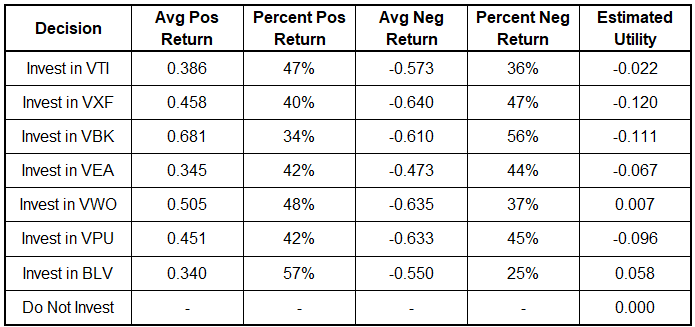

Therefore, based on the analysis of the data available for the first week in January from 2008 to 2018, the optimal ETF to invest in for the first week of January 2019 is BLV. This means that the investor should choose to buy BLV on January 1 and sell it on January 7, at which point a new decision must be made for the next week.

It is important to note that the chance of a positive return and the chance of a negative return does not necessarily have to add up to 1. Since seven consecutive calendar dates must include weekends, which are not trading days, there will be some data points that have a net-zero return, which have no bearing on the utility function.

**DATA ANALYSIS WITH MATLAB**

1) Start by importing each .csv file containing pre-processed data of daily returns for all seven ETFs. Create a matrix called "ETF" to hold all of the data in one place with a common reference name and populate it with the ETF data. Also, import another matrix that holds a data set created to store a "calendar" for later data processing. It will be important later to sort through the trading data and pair information by like days.

ETF = zeros(3020,4,7);
VTI = csvread('VTI1.csv'); ETF(:,:,1) = VTI(:,:);
VXF = csvread('VXF2.csv'); ETF(:,:,2) = VXF(:,:);
VBK = csvread('VBK3.csv'); ETF(:,:,3) = VBK(:,:);
VEA = csvread('VEA4.csv'); ETF(:,:,4) = VEA(:,:);
VWO = csvread('VWO5.csv'); ETF(:,:,5) = VWO(:,:);
VPU = csvread('VPU6.csv'); ETF(:,:,6) = VPU(:,:);
BLV = csvread('BLV7.csv'); ETF(:,:,7) = BLV(:,:);
Dates = csvread('YearlyData.csv');

2) To test the code, there is are inputs built in to choose the range of years to use in data analysis. By changing these variables below, different scenarios can be run to test the effectiveness of the method. This is how the decision maker can simulate a decision in the past. For this demonstration of the code, the decision maker is sorting from 2008 to 2018 to make a decision about what strategy to follow for 2019. At the end of the code, 2019 will be evaluated using the determined strategy. There is also an input to choose the number of days between each decision node. As discussed, this analysis will be done on a week-to-week basis, but the methodology can be changed by changing the "DaysAvg" variable.

StartYear=2008;
EndYear=2018;
DaysAvg = 7;

3) Create a matrix to hold the averaged data for each year, both for positive and negative, and populate with the data. This matrix will hold the data for each individual calendar day and will be combined later to evaluate an entire week.

- Column 1 = month

- Column 2 = day of the month

- Column 3 = percentage of days

- Column 4 = average return for those days

PosDays = zeros(366,4,7); PosDays(:,1:2,1) = Dates(:,:);
NegDays = zeros(366,4,7); NegDays(:,1:2,1) = Dates(:,:);

for fund = 1:7
    for day = 1:366
        %create temporary variables to use in assessing data as positive
        %and negative for each calendar day
        PosETFcount=0; PosETFtotal=0; 
        NegETFcount=0; NegETFtotal=0; ZeroETFcount=0;
        for data = 1:size(ETF,1)
            %Go through each date in ETF and see if it matches the calendar
            %date that is in my second for loop
            if(ETF(data,1,fund)==PosDays(day,1,1) && ...
               ETF(data,2,fund)==PosDays(day,2,1))
                %if between years of interest and value is positive
                if(ETF(data,3,fund)>=StartYear && ...
                   ETF(data,3,fund)<=EndYear && ETF(data,4,fund)>0)
                    %count number of days of positive return
                    PosETFcount=PosETFcount+1;
                    %keep the total value to get average at the end
                    PosETFtotal=PosETFtotal+ETF(data,4,fund);
                end
                %if between years of interest and value is negative
                if(ETF(data,3,fund)>=StartYear && ...
                   ETF(data,3,fund)<=EndYear && ETF(data,4,fund)<0)
                    %count number of negative days
                    NegETFcount=NegETFcount+1;
                    %keep the total value to get average at the end
                    NegETFtotal=NegETFtotal+ETF(data,4,fund);
                end
                %if between years of interest and value is 0
                if(ETF(data,3,fund)>=StartYear && ...
                   ETF(data,3,fund)<=EndYear && ETF(data,4,fund)==0)
                    %count number of net-zero days
                    ZeroETFcount=ZeroETFcount+1;
                end         
            end 
        end
        
        %add up how many trading days there were for those years
        TotalETFdays=PosETFcount+NegETFcount+ZeroETFcount;
        
        %only run the code below if the total trading days was >0
        %important because the code runs even for holidays which are never
        %trading days
        if TotalETFdays>0
            %calculate the percent of days return was positive
            PosDays(day,3,fund)=PosETFcount/TotalETFdays;
            %if there are any positive days, solve the average pos return
            if PosETFcount>0
                PosDays(day,4,fund)=PosETFtotal/PosETFcount;
            end
            %calculate the percent of days return was negative
            NegDays(day,3,fund)=NegETFcount/TotalETFdays;
            %if there are any negative days, solve the average neg return
            if NegETFcount>0
                NegDays(day,4,fund)=NegETFtotal/NegETFcount; %average positive
            end
        end
    end
end

4) Solve the utility function to use in the decision making process. The Utility matrix has 12 columns.

- Columns 1-7 = estimated utility for each ETF in the same order as ETF matrix

- Column 8 = all zeros to represent utility of decision 8 (do not trade)

- Columns 9-10 = date information (9 = month, 10 = day of month)

- Column 11 = decision number (1-8) with the highest estimated utility

- Column 12 = corresponding estimated utility value of the optimal decision

Utility = zeros(366,12); Utility(:,9:10) = PosDays(:,1:2);

for day = 1:366
    %calculate the utility for each etf on each day
    %Utility = (perc pos)(avg pos value) + (perc neg)(avg neg value)
    Utility(day,1)=PosDays(day,3,1)*PosDays(day,4,1) + ...
        NegDays(day,3,1)*NegDays(day,4,1);
    Utility(day,2)=PosDays(day,3,2)*PosDays(day,4,2) + ...
        NegDays(day,3,2)*NegDays(day,4,2);
    Utility(day,3)=PosDays(day,3,3)*PosDays(day,4,3) + ...
        NegDays(day,3,3)*NegDays(day,4,3);
    Utility(day,4)=PosDays(day,3,4)*PosDays(day,4,4) + ...
        NegDays(day,3,4)*NegDays(day,4,4);
    Utility(day,5)=PosDays(day,3,5)*PosDays(day,4,5) + ...
        NegDays(day,3,5)*NegDays(day,4,5);
    Utility(day,6)=PosDays(day,3,6)*PosDays(day,4,6) + ...
        NegDays(day,3,6)*NegDays(day,4,6);
    Utility(day,7)=PosDays(day,3,7)*PosDays(day,4,7) + ...
        NegDays(day,3,7)*NegDays(day,4,7);
    
    %solve maximum utility and identify the decision choice
    %column 11 holds the etf number, 12 holds corresponding estimated utility
    [Utility(day,12) Utility(day,11)]=max(Utility(day,1:8));
    %if the date is a holiday, force decision to be "do not trade"
    if sum(Utility(day,1:7))==0
        Utility(day,11) = 8;
    end
end

5) Implement the multi-day average decision making. This is done by averaging the estimated utility of each day in the week for each ETF. 

for period = 1:ceil(366/DaysAvg)
    
    %Average data points for that period, reset to zeros
    SumUtility_Period = zeros(1,8);
    
    %handle the first "period" (stretch of days) separately
    if (period == 1)
        for day = 1:DaysAvg
            %fill the sum array with total for each utility for period
            SumUtility_Period(1) = SumUtility_Period(1)+Utility(day,1);
            SumUtility_Period(2) = SumUtility_Period(2)+Utility(day,2);
            SumUtility_Period(3) = SumUtility_Period(3)+Utility(day,3);
            SumUtility_Period(4) = SumUtility_Period(4)+Utility(day,4);
            SumUtility_Period(5) = SumUtility_Period(5)+Utility(day,5);
            SumUtility_Period(6) = SumUtility_Period(6)+Utility(day,6);
            SumUtility_Period(7) = SumUtility_Period(7)+Utility(day,7);
        end 
        
    %for all periods of days in between
    elseif (period < ceil(366/DaysAvg))
        for day_period=1:DaysAvg
            day = (period-1)*DaysAvg+day_period;
            SumUtility_Period(1) = SumUtility_Period(1)+Utility(day,1);
            SumUtility_Period(2) = SumUtility_Period(2)+Utility(day,2);
            SumUtility_Period(3) = SumUtility_Period(3)+Utility(day,3);
            SumUtility_Period(4) = SumUtility_Period(4)+Utility(day,4);
            SumUtility_Period(5) = SumUtility_Period(5)+Utility(day,5);
            SumUtility_Period(6) = SumUtility_Period(6)+Utility(day,6);
            SumUtility_Period(7) = SumUtility_Period(7)+Utility(day,7);
        end 
        
    %for the last period which is likely not a full length period
    else
        for day = (period-1)*DaysAvg:366
            SumUtility_Period(1) = SumUtility_Period(1)+Utility(day,1);
            SumUtility_Period(2) = SumUtility_Period(2)+Utility(day,2);
            SumUtility_Period(3) = SumUtility_Period(3)+Utility(day,3);
            SumUtility_Period(4) = SumUtility_Period(4)+Utility(day,4);
            SumUtility_Period(5) = SumUtility_Period(5)+Utility(day,5);
            SumUtility_Period(6) = SumUtility_Period(6)+Utility(day,6);
            SumUtility_Period(7) = SumUtility_Period(7)+Utility(day,7);
        end
    end
    
    %divide by the period to get the expected utility for each day
    SumUtility_Period = SumUtility_Period/DaysAvg;
    
    %find ETF with best utility for the period
    %overwrite the same utility matrix from single day analysis above
    %Utility 11 = best etf number
    %Utility 12 = expected utility of the decision
    
    if (period == 1)
        for day=1:DaysAvg
            [Utility(day,12) Utility(day,11)]=max(SumUtility_Period);
        end
        
    elseif (period < ceil(366/DaysAvg))
        for day_period=1:DaysAvg
            day = (period-1)*DaysAvg+day_period;
            [Utility(day,12) Utility(day,11)]=max(SumUtility_Period);
        end
        
    else
        for day = (period-1)*DaysAvg:366
            [Utility(day,12) Utility(day,11)]=max(SumUtility_Period);
        end
    end 
end

6) Sum up the total estimated utility and print it out.This theoretically represents the return that the decision maker can expect for the next year based on historical data.

TotalEstimatedUtility = sum(Utility(:,12))

TotalEstimatedUtility = 38.1664

7) Check the actual return for all years in the data set 2008-2019 based on the strategy that was just defined in step 4. The matrix "YearReturns" is created and used to hold the data. 

- Columns 1-2 = date information, both month and day

- Columns 3-7 = no information

- Columns 8-19 = returns for each day based on the defined strategy

YearReturns = zeros(366,19); YearReturns(:,1:2)=Utility(:,9:10);
%go through each day for every year to find the actual return of
%theoretically following the strategy just solved for
for year = 8:19
    for day = 1:366
        for data = 1:3020
            %make sure the code accesses the correct data by date
            if(ETF(data,1,1)==YearReturns(day,1) && ...
               ETF(data,2,1)==YearReturns(day,2) && ...
               ETF(data,3,1)==2000+year && Utility(day,11)<8)
                %populate value with what would have been chosen given the
                %strategy was followed exactly
                YearReturns(day,year) = ETF(data,4,Utility(day,11));
            end
        end
    end
end

8) Print out the results of the strategy if used for the past years (in this case, 2008-2018). Also print the results of the strategy if followed "in the future". The code will work to analyze and solve any stretch of years of data, but in this case it will only be printing out the results of 2019 based on the example.

PerformanceByYearPast=zeros(2,EndYear-2008+1);
PerformanceByYearPast(1,:)=2008-2000:EndYear-2000;

for year = 1:length(PerformanceByYearPast)
    PerformanceByYearPast(2,year)=sum(YearReturns(:,2008-2000+year-1));
end

%print it out, leave out 2008 to make output fit in document
PerformanceByYearPast(:,2:end)'

ans =     9.0000   40.4623
   10.0000   15.4631
   11.0000   35.7346
   12.0000   16.4297
   13.0000   13.5758
   14.0000   17.6781
   15.0000    9.6781
   16.0000   36.0843
   17.0000   14.3635
   18.0000   10.4159


%check the years in the future after EndYear
%this only runs if your search used data before 2019
if(EndYear<2019)
    PerformanceByYearFuture=zeros(2,2019-EndYear);
    PerformanceByYearFuture(1,:)=EndYear-2000+1:2019-2000;
    for year = 1:2019-EndYear
        PerformanceByYearFuture(2,year)=sum(YearReturns(:,year+EndYear-2000));
    end
    PerformanceByYearFuture'
end

ans =    19.0000    2.9887


9) Also print out the returns of each individual ETF using the buy-and-hold approach used to create the benchmark in this project. The description of what it says is shown below. The results are only evaluated for a single year (in this case, 2019). Though the ultimate goal of the paper is to assess the aggregate returns of multiple years, the code only evaluates one year at a time, and the results of this output give an idea of the single year performance of the strategy versus the actual returns of individual funds. The aggregate data was collected by running multiple samples of this code and is presented in the *Assessing Performance of the Seasonal Method Using Aggregate Results* section below.

- Column 1 = year

- Column 2 = VTI

- Column 3 = VXF

- Column 4 = VBK

- Column 5 = VEA

- Column 6 = VWO

- Column 7 = VPU

- Column 8 = BLV

if(EndYear<2019)
    FutureYearsETF_BuyHold=zeros(2019-EndYear,8);
    FutureYearsETF_BuyHold(:,1)=EndYear-2000+1:2019-2000;
    for year = EndYear+1:2019
        firstIndex = find(ETF(:,3,1)==year,1,'first');
        lastIndex = find(ETF(:,3,1)==year,1,'last');
        for ETFnum=1:7
            FutureYearsETF_BuyHold(year-EndYear,ETFnum+1)=...
                sum(ETF(firstIndex:lastIndex,4,ETFnum));
        end
    end
    %print out the data
    FutureYearsETF_BuyHold
end

FutureYearsETF_BuyHold =    19.0000   12.1955    8.4811   11.9115   12.3005    9.4018   12.6247    3.4094


**ASSESSING PERFORMANCE OF THE SEASONAL METHOD USING AGGREGATE RESULTS**

Based on the example set up in this report, the 2019 strategy produced a 2.99% return, which was less than the actual return of each individual ETF. This is a disappointing result, but only represents one strategy, and the true evaluation of the method must be done by looking at the aggregate returns of multiple years. The following table presents the individual returns of each ETF from 2013-2019 side by side with the results of the diversification approach used as the prior beliefs and the seasonal strategy used for each year. The bottom row is the aggregate return of following each column for that stretch of years.

TABLE 6: INDIVIDUAL AND AGGREGATE RESULTS

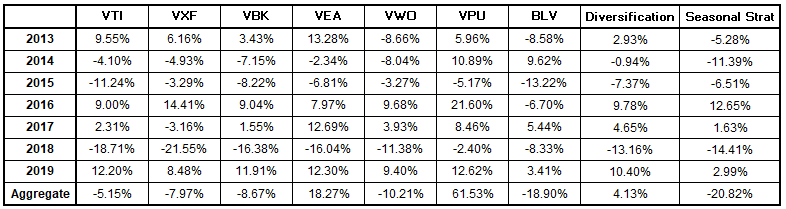

Ouch! This data shows that seasonal investment based on a week-to-week decision making approach is completely worthless. The aggregate return of creating and following a strategy from 2013-2019 using data starting in 2008 was lower than investing in any particular ETF over the same period. The seasonal approach also performed much worse than the diversification approach used as the prior beliefs for this analysis. Diversification is in fact the most conservative approach, because it takes the thinking out of investing and attempts to capture the overall performance of the market. In this exercise, this conservative, hands-off approach dramatically outperformed the aggressive, hands-on seasonal investing approach.

#### SUMMARY AND CONCLUSION

In conclusion, the methodology used in this project for seasonal investing does not work. It was not able to outperform a buy-and-hold approach. This does not mean that seasonal investing is not a worthwhile concept, however. It is possible to use a different decision making approach and a different set of ETFs to find a way of beating buy-and-hold, but this method was unsuccessful.